# MATLAB Statistics & Machine Learning Toolbox Demo

**Date: **20 March 2026

## SECTION 1: Exploratory Data Analysis & Visualisation

### 1.1 Exploratory Analysis of Data

**Source:** [https://www.mathworks.com/help/stats/exploratory-analysis-of-data.html](https://www.mathworks.com/help/stats/exploratory-analysis-of-data.html) 

**Open live script:** openExample('stats/ExploratoryAnalysisOfDataExample')

**Why it's relevant:** Before applying any ML or SPC method, engineers need to understand the shape and spread of their process data (e.g., placement accuracy, solder paste volume, inspection measurements). This example shows how to generate summary statistics (mean, std, skewness, kurtosis) and visualise distributions with box plots, histograms, and probability plots — a natural starting point for any data analysis workflow.

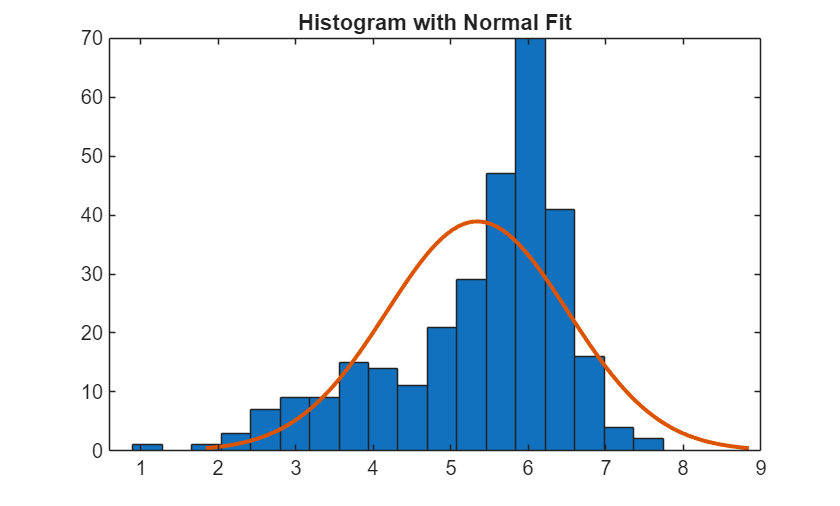

% Generate Data
% Combine 100 observations from N(4,1) with 200 from N(6,0.5)
rng(0,"twister") % For reproducibility
x = [normrnd(4,1,1,100), normrnd(6,0.5,1,200)];

% Visualize Data: histogram with normal density fit
histfit(x)
title('Histogram with Normal Fit')

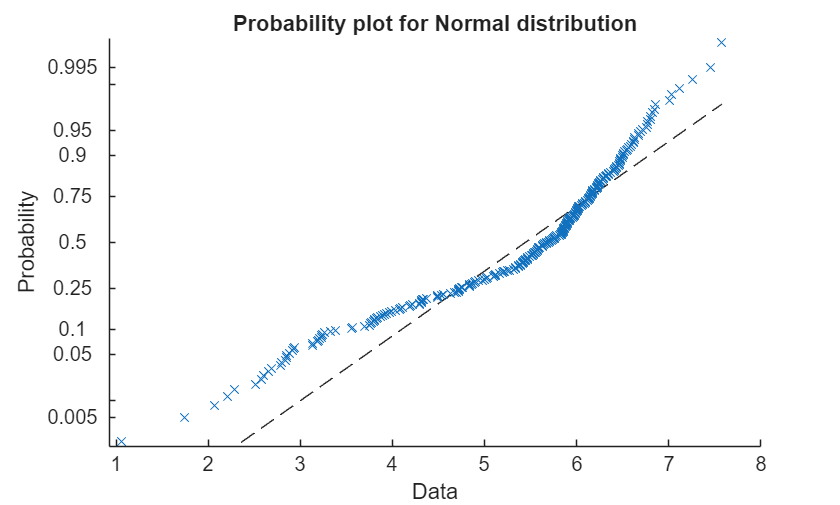


% Normal probability plot
figure
probplot("normal", x)

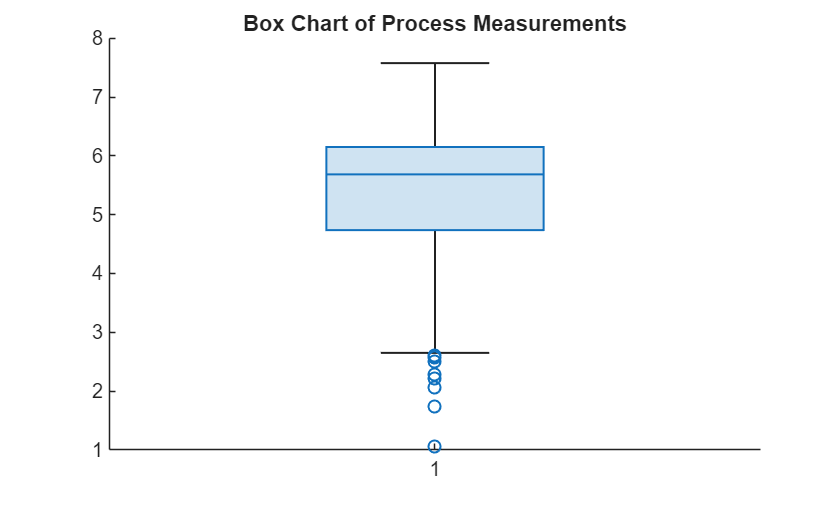


% Box plot to visualise spread and outliers
figure
boxchart(x)
title('Box Chart of Process Measurements')


% Compute Descriptive Statistics
y1 = [mean(x), median(x)]

y1 =     5.3438    5.6872


y2 = [skewness(x), kurtosis(x)]

y2 =    -1.0417    3.5895



% Identify potential outliers via z-scores (|z| > 3)
z = zscore(x);
outlierIdx = find(abs(z) > 3)

outlierIdx =      3    35


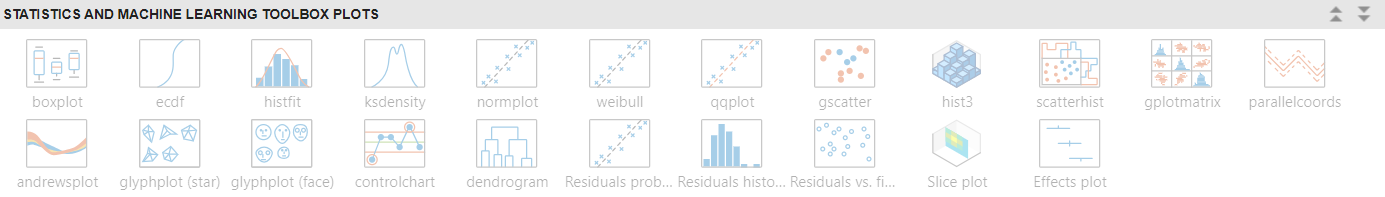

### 1.2 Visualize Multivariate Data

**Source:** [https://www.mathworks.com/help/stats/visualizing-multivariate-data.html](https://www.mathworks.com/help/stats/visualizing-multivariate-data.html) 

**Open live script:** openExample('stats/mvplotdemo')

**Why it's relevant:** SMT manufacturing produces high-dimensional sensor data across multiple machines and process parameters simultaneously. This example demonstrates scatter plot matrices, parallel coordinate plots, and grouped visualisations to reveal correlations and patterns across many variables at once — essential for understanding multi-axis machine data.

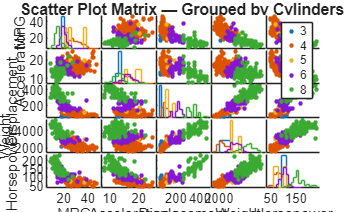

% Load the carbig dataset (cars with multi-variable measurements)
load carbig
X = [MPG, Acceleration, Displacement, Weight, Horsepower];
varNames = ["MPG","Acceleration","Displacement","Weight","Horsepower"];

% Scatter Plot Matrix — all bivariate relationships at a glance,
% grouped by number of cylinders (analogous to grouping by machine/line)
figure
gplotmatrix(X, [], Cylinders, [], [], 8, [], [], varNames)
title('Scatter Plot Matrix — Grouped by Cylinders')

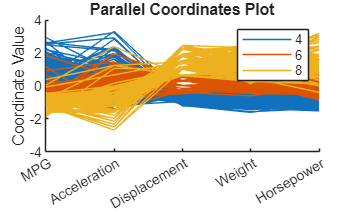


% Parallel Coordinates Plot — all variables simultaneously
cyl468 = ismember(Cylinders, [4 6 8]);
figure
parallelcoords(X(cyl468,:), Group=Cylinders(cyl468), ...
    Standardize="on", Labels=varNames)
title('Parallel Coordinates Plot')

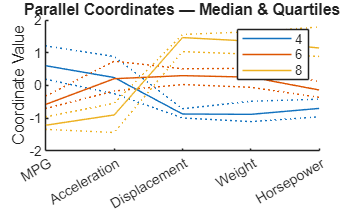


% Quantile-based parallel coords — cleaner view with less overplotting
figure
parallelcoords(X(cyl468,:), Group=Cylinders(cyl468), ...
    Standardize="on", Labels=varNames, Quantile=0.25)
title('Parallel Coordinates — Median & Quartiles')

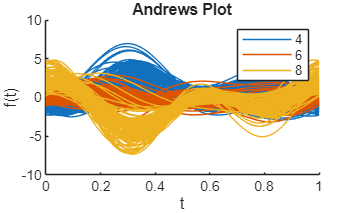


% Andrews Plot — smooth function representation of each observation
figure
andrewsplot(X(cyl468,:), Group=Cylinders(cyl468), Standardize="on")
title('Andrews Plot')

## SECTION 2: Statistical Process Control (SPC) & Process Capability

### 2.1 Process Capability Analysis

**Source:** [https://www.mathworks.com/help/stats/capability.html](https://www.mathworks.com/help/stats/capability.html) [https://www.mathworks.com/help/stats/capaplot.html](https://www.mathworks.com/help/stats/capaplot.html)

**Why it's relevant:** Process capability indices (Cp, Cpk) are a core quality metric in SMT manufacturing — used to verify that a machine's output (e.g., component placement offsets, solder paste height) consistently meets specification limits. This demonstrates computing Cp/Cpk and generating capability plots directly from process measurement data.

% Simulate 100 measurements from a process: mean=3, std=0.005
rng(0,"twister")
data = normrnd(3, 0.005, 100, 1);

% Specification limits (e.g., nominal 3mm +/- 0.01mm)
specs = [2.99, 3.01];

% Compute capability indices
S = capability(data, specs)

S = struct with fields:
       mu: 3.0006
    sigma: 0.0058
        P: 0.9129
       Pl: 0.0339
       Pu: 0.0532
       Cp: 0.5735
      Cpl: 0.6088
      Cpu: 0.5382
      Cpk: 0.5382


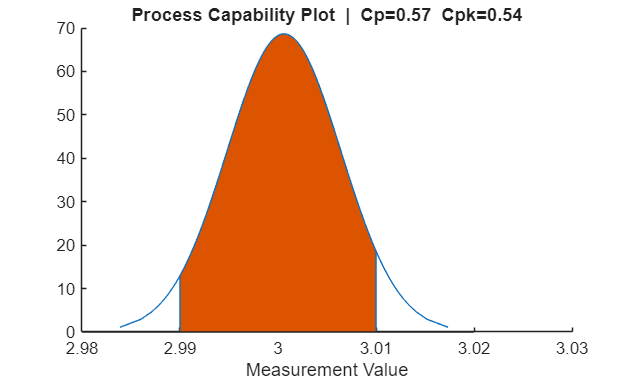

% S.Cp  — potential capability (ignores mean shift)
% S.Cpk — actual capability (accounts for mean position)
% Rule of thumb: Cpk >= 1.33 is acceptable; >= 1.67 is excellent

% Capability plot: visualises the fitted distribution vs spec limits
figure
p = capaplot(data, specs);
title(sprintf('Process Capability Plot  |  Cp=%.2f  Cpk=%.2f', S.Cp, S.Cpk))
xlabel('Measurement Value')

### 2.2 Shewhart Control Charts (X-bar & R)

**Source:** [https://www.mathworks.com/help/stats/controlchart.html](https://www.mathworks.com/help/stats/controlchart.html) [https://www.mathworks.com/help/stats/controlrules.html](https://www.mathworks.com/help/stats/controlrules.html)

**Why it's relevant:** Control charts are the industry standard tool for monitoring whether an SMT process (e.g., printer deposit volume, pick-and-place accuracy) is in statistical control. This example shows how to generate X-bar and R charts and detect out-of-control signals using Western Electric rules.

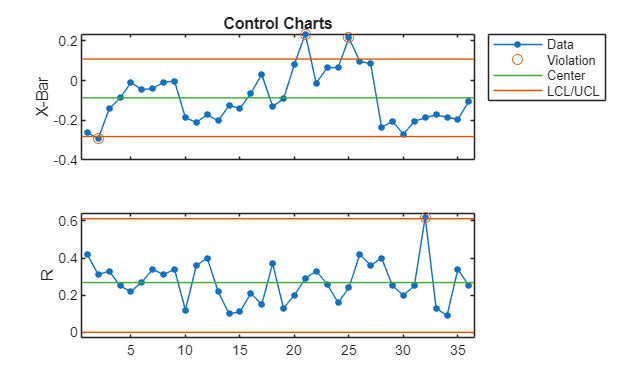

% Load the 'runout' dataset — 36 subgroups of 4 measurements each
load parts  % loads 'runout' matrix (36x4)

% Create X-bar and R control charts; return subgroup statistics
figure
stats = controlchart(runout, ChartType=["xbar","r"]);

% Circled points indicate subgroups that violate control limits

% Display process estimates
fprintf('Process mean (mu): %.4f\n', stats.mu)

Process mean (mu): -0.0864


fprintf('Process std  (sigma): %.4f\n', stats.sigma)

Process std  (sigma): 0.1302


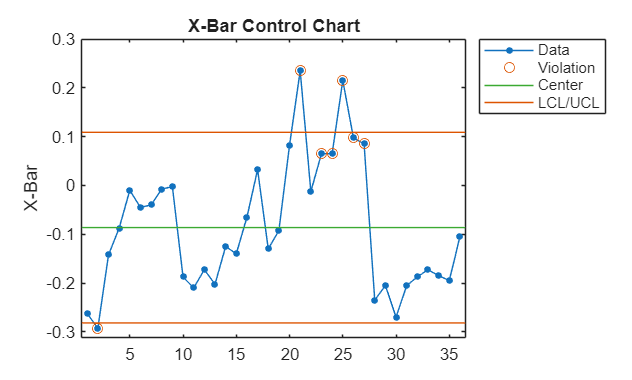


% Apply Western Electric Rule 2 (we2): 2 of 3 consecutive points
% >= 2 sigma from centre line — flag potential shifts early
figure
[st2, plotted] = controlchart(runout, Rules="we2");


% Identify the exact subgroup numbers that triggered the rule
x_pts = st2.mean;
cl    = st2.mu;
se    = st2.sigma ./ sqrt(st2.n);
R     = controlrules("we2", x_pts, cl, se);
violatingSubgroups = find(R)

violatingSubgroups =     21
    23
    24
    25
    26
    27


### 2.3 Gage Repeatability & Reproducibility (Gage R&R)

**Source:** [https://www.mathworks.com/help/stats/gagerr.html](https://www.mathworks.com/help/stats/gagerr.html)

**Why it's relevant:** Before trusting any measurement data, we need to validate its measurement systems (e.g., AOI, SPI, inline sensors). Gage R&R quantifies how much of the total measurement variation comes from the measurement system itself versus true part-to-part variation. This is a mandatory analysis in any Six Sigma or MSA program.



         Source          Variance     PercentVariance     Sigma     StudyVariation    PercentStudyVariation
    _________________    _________    _______________    _______    ______________    _____________________

    Gage R&R               0.95348         99.251        0.97646        5.0288               99.625        
      Repeatability        0.95348         99.251        0.97646        5.0288               99.625        
      Reproducibility            0              0              0             0                    0        
    Part                 0.0071911        0.74854         0.0848       0.43672               8.6518        
    Total                  0.96067            100        0.98014        5.0477                             

Study Variation: 5.15*Sigma
Number o

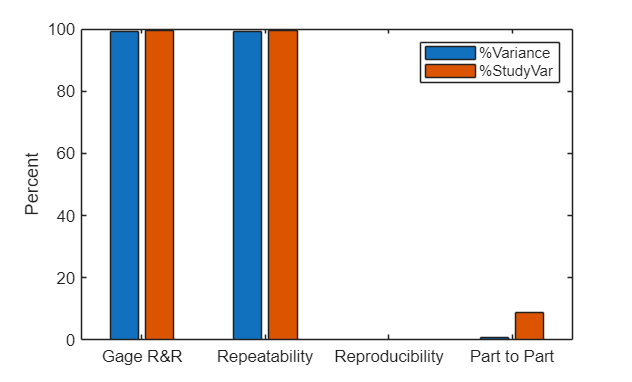

% Simulate a measurement data set by randomly generating 100 measurements y of three parts. 
% Each measurement is collected by one of four randomly assigned operators.
rng(1234,"twister"); % For reproducibility
n = 100;
y = randn(n,1);                
part = randi([1,3],1,n);       
operator = randi([1,4],1,n);  

% Perform a Gage repeatability and reproducibility (R&R) study on this data set using a mixed ANOVA model without interactions.
gagerr(y,{part,operator},RandomOperator=false)

### 2.4 Improve Process Performance Using Design for Six Sigma (DMAIC)

**Source:** [https://www.mathworks.com/help/stats/improve-engine-cooling-fan-performance-using-design-for-six-sigma-techniques.html](https://www.mathworks.com/help/stats/improve-engine-cooling-fan-performance-using-design-for-six-sigma-techniques.html) 

**Open live script:** openExample('stats/ImproveEngineCoolingFanPerformanceExample')

**Why it's relevant:** This end-to-end example walks through the Define-Measure-Analyse-Improve- Control methodology applied to an engineering optimisation problem.  

Key steps shown: 

- MEASURE — Gage R&R on current measurement system 

- ANALYSE — ANOVA to identify significant factors 

- IMPROVE — DOE (fractional factorial) to optimise settings 

- CONTROL — Control charts to sustain gains

 Run the above command to open the full interactive live script

## SECTION 3: Regression — Predicting Process Outcomes

### 3.1 Train Regression Models Using Regression Learner App

**Source:** [https://www.mathworks.com/help/stats/train-regression-models-in-regression-learner-app.html](https://www.mathworks.com/help/stats/train-regression-models-in-regression-learner-app.html)

**Why it's relevant:** The Regression Learner App lets engineers interactively train, compare, and export regression models (linear, tree, GPR, SVM, ensembles, neural nets) without writing code — directly applicable to predicting yield, cycle time, or defect rates from process parameters. No prior ML experience needed.

% STEP 1 — Load a dataset into the workspace
load carbig
tbl = table(Displacement, Horsepower, Weight, Acceleration, MPG);
tbl = rmmissing(tbl);  % remove rows with NaN

% STEP 2 — Launch the Regression Learner App
regressionLearner(tbl, "MPG")
% In the app:
%   * Start Session: select table 'tbl', response = 'MPG', 5-fold CV
%   * Click "Train All" to automatically train all model types
%   * Compare RMSE values in the models pane
%   * Select best model -> Export -> Export Model to Workspace

% STEP 3 — After export, use the model to predict on new data:
% yfit = trainedModel.predictFcn(newDataTable);

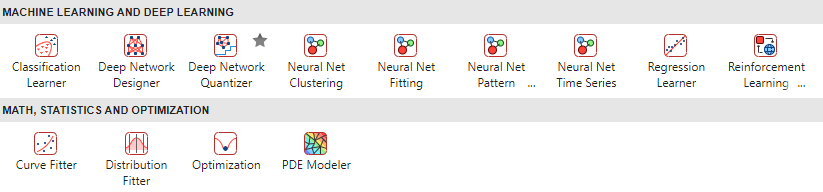

### 3.2 Detect Outliers Using Quantile Regression

**Source:** [https://www.mathworks.com/help/stats/outlier-detection-using-quantile-regression.html](https://www.mathworks.com/help/stats/outlier-detection-using-quantile-regression.html) 

**Open live script:** openExample('stats/OutlierDetectionUsingQuantileRegressionExample')

**Why it's relevant:** Outliers in process data — caused by machine faults, material variation, or operator error — can corrupt regression models and statistical analyses. This example uses quantile random forests to build adaptive fences around the data, robustly flagging anomalies even for heteroscedastic (non-uniform variance) manufacturing data.

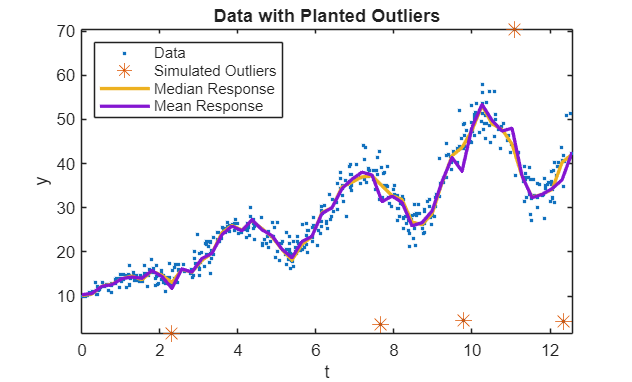

% Generate nonlinear heteroscedastic data with 5 planted outliers
n = 500;
rng('default')  % For reproducibility
t = randsample(linspace(0, 4*pi, 1e6), n, true)';
epsilon = randn(n,1) .* sqrt((t + 0.01));
y = 10 + 3*t + t.*sin(2*t) + epsilon;
Tbl = table(t, y);

% Plant 5 outliers — shift them vertically by 90% of the response value
nout = 5;
idx = randsample(n, nout);
Tbl.y(idx) = Tbl.y(idx) .* (1 + 0.9*sign(randn(nout,1)));

% Scatter plot of data with planted outliers highlighted
figure
plot(Tbl.t, Tbl.y, '.');
hold on
plot(Tbl.t(idx), Tbl.y(idx), '*', 'MarkerSize', 10);
axis tight
xlabel('t'); ylabel('y');
title('Data with Planted Outliers')
legend('Data', 'Simulated Outliers', 'Location', 'NorthWest')

% Grow a bag of 200 regression trees and predict conditional quartiles
Mdl = TreeBagger(200, Tbl, 'y', 'Method', 'regression');
tau = [0.25 0.5 0.75];
predT = linspace(0, 4*pi, 50)';
quartiles = quantilePredict(Mdl, predT, 'Quantile', tau);
meanY = predict(Mdl, predT);

% Plot quartile regression bands on the scatter plot
hold on
plot(predT, [quartiles(:,2) meanY], 'LineWidth', 2)
legend('Data','Simulated Outliers','Median Response','Mean Response', ...
    'Location','NorthWest')

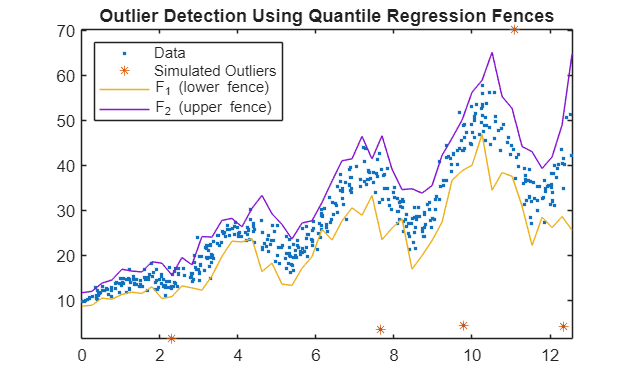


% Define IQR-based fences: k=1.5 = standard outlier, k=3 = extreme outlier
k = 1.5;
IQR_pred = quartiles(:,3) - quartiles(:,1);
f1 = quartiles(:,1) - k * IQR_pred;
f2 = quartiles(:,3) + k * IQR_pred;

figure
plot(Tbl.t, Tbl.y, '.'); hold on
plot(Tbl.t(idx), Tbl.y(idx), '*')
plot(predT, [f1 f2])
legend('Data','Simulated Outliers','F_1 (lower fence)','F_2 (upper fence)', ...
    'Location','NorthWest')
axis tight
title('Outlier Detection Using Quantile Regression Fences')

## SECTION 4: Classification — Detecting Faults & Categorising Quality

### 4.1 Train Decision Trees Using Classification Learner App

**Source:** [https://www.mathworks.com/help/stats/train-decision-trees-using-classification-learner-app.html](https://www.mathworks.com/help/stats/train-decision-trees-using-classification-learner-app.html)

**Why it's relevant:** A common problem in SMT quality inspection is classifying boards or components as "pass" or "fail" based on inspection data. Decision trees are highly interpretable — engineers can read the decision rules directly. This example steps through the full Classification Learner workflow.

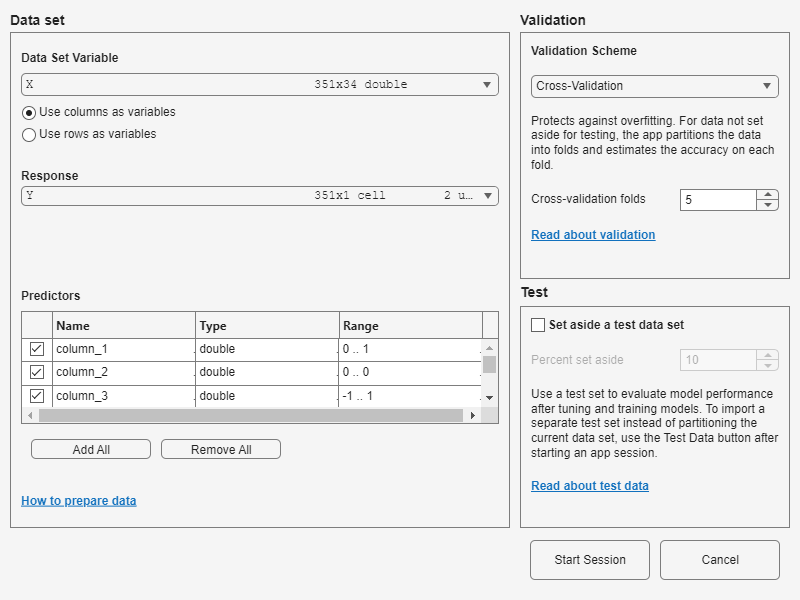

% Load example data (radar signal classification — 34 features, 2 classes)
load ionosphere  % X (351x34), Y ('b' = bad, 'g' = good ionosphere)

% Launch Classification Learner App
classificationLearner(X, Y)

% In the app:
%   * Start Session: select X (predictors), Y (response), 5-fold CV
%   * Models gallery -> Decision Trees group -> click "Fine Tree"
%   * Click Train; inspect confusion matrix and ROC curve
%   * Add Medium Tree, Coarse Tree to compare accuracy vs complexity
%   * Export best model to workspace

% After export, predict new observations:
% predictedLabel = trainedModel.predictFcn(newX);

### 4.2 Build a Condition Model for Industrial Machinery

**Source:** [https://www.mathworks.com/help/stats/build-condition-model-for-industrial-machinery-and-manufacturing-processes.html](https://www.mathworks.com/help/stats/build-condition-model-for-industrial-machinery-and-manufacturing-processes.html)

**Why it's relevant:**  This example builds a binary classification model on vibration sensor data from a manufacturing machine to distinguish "after maintenance" (normal) from "before maintenance" (degraded/anomalous) states. Directly analogous to monitoring SIPLACE placement heads, DEK printers, or conveyor systems for maintenance scheduling.

The workflow: 

    1. Load vibration sensor feature data (12 features, 2 class labels) 

    2. Import into Classification Learner; hold out 10% as test set 

    3. Train multiple model types: Bagged Trees, Fine Gaussian SVM, Bilayered Neural Network 

    4. Compare validation accuracy; identify best model 

    5. Use feature selection to reduce from 12 to fewer features 

    6. Re-train on reduced feature set; confirm accuracy maintained 

    7. Export compact model; use predict() for real-time monitoring

STEP 1 — Open the full example to get the featureAll dataset: >> openExample('stats/BuildConditionModelForIndustrialMachineryExample')

STEP 2 — After loading featureAll (table with 'label' response column): classificationLearner(featureAll, "label", TestDataFraction=0.1)

STEP 3 — In the app, add these model types from the Models gallery: Ensemble Classifiers -> Bagged Trees Support Vector Machines -> Fine Gaussian SVM Neural Network -> Bilayered Neural Network

STEP 4 — Click "Train All", compare accuracy in the Models pane

STEP 5 — Feature selection within the app: Learn tab -> Feature Selection -> rank by importance Deselect low-importance features -> re-train -> check accuracy

STEP 6 — Export best compact model to workspace: Export -> Export Model -> uncheck "Include training data"

STEP 7 — Predict condition of new sensor readings in production: conditionLabel = trainedModel.predictFcn(newSensorReadings);

### 4.3 Feature Selection and Feature Transformation

**Source:** [https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html)

**Why it's relevant:** SMT machines generate tens or hundreds of sensor signals per cycle. Feature ranking identifies the most predictive signals, reducing model size for deployment on embedded or edge hardware with limited resources.

% Load data
load ionosphere

% Rank features using ReliefF algorithm (robust to noisy/redundant features)
[ranked, weights] = relieff(X, Y, 10);
fprintf('Top 5 features by ReliefF importance rank: %s\n', num2str(ranked(1:5)))

Top 5 features by ReliefF importance rank: 24   3   8   5  14


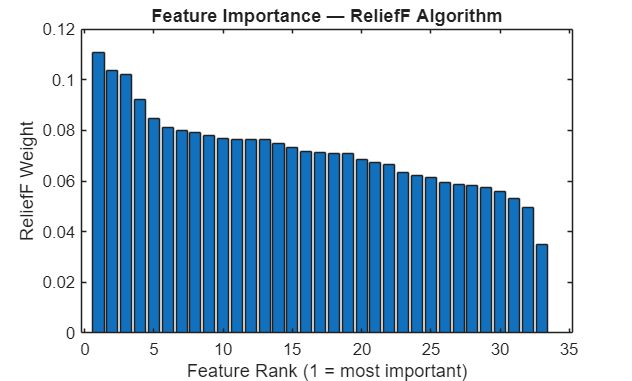


% Visualise feature importance weights in rank order
figure
bar(weights(ranked))
xlabel('Feature Rank (1 = most important)')
ylabel('ReliefF Weight')
title('Feature Importance — ReliefF Algorithm')

## SECTION 5: Anomaly Detection — Finding Defects in Unlabelled Data

### 5.1 Unsupervised Anomaly Detection

**Source: **[https://www.mathworks.com/help/stats/unsupervised-anomaly-detection.html](https://www.mathworks.com/help/stats/unsupervised-anomaly-detection.html)

**Open live script:** openExample('stats/UnsupervisedAnomalyDetectionExample')

**Why it's relevant:** In many scenarios, labelled defect data is scarce or unavailable. These unsupervised methods work purely on "normal" process data to flag unusual observations — no pre-labelled fault examples required. This example compares five methods side-by-side so engineers can select the best fit for their data.

% Load human activity dataset (60 features, 24075 observations)
load humanactivity  % variables: feat (24075x60), actid (24075x1)

% Assume 5% of observations are anomalies
contaminationFraction = 0.05;

% --- Method 1: Isolation Forest ---
rng("default")  % For reproducibility
[forest, tf_forest, s_forest] = iforest(feat, ...
    ContaminationFraction=contaminationFraction);
fprintf('Isolation Forest:  %d anomalies detected (out of %d)\n', ...
    sum(tf_forest), numel(tf_forest))

Isolation Forest:  1195 anomalies detected (out of 24075)



% --- Method 2: Local Outlier Factor (LOF) ---
[lofMdl, tf_lof, s_lof] = lof(feat, ...
    ContaminationFraction=contaminationFraction);
fprintf('Local Outlier Factor: %d anomalies detected\n', sum(tf_lof))

Local Outlier Factor: 1204 anomalies detected



% --- Method 3: One-Class SVM ---
[ocsvmMdl, tf_ocsvm, s_ocsvm] = ocsvm(feat, ...
    ContaminationFraction=contaminationFraction);
fprintf('One-Class SVM:     %d anomalies detected\n', sum(tf_ocsvm))

One-Class SVM:     1204 anomalies detected



% Compare agreement between methods
fprintf('Isolation Forest vs LOF agreement:      %.1f%%\n', ...
    mean(tf_forest == tf_lof)*100)

Isolation Forest vs LOF agreement:      91.1%


fprintf('Isolation Forest vs One-Class SVM:      %.1f%%\n', ...
    mean(tf_forest == tf_ocsvm)*100)

Isolation Forest vs One-Class SVM:      90.9%


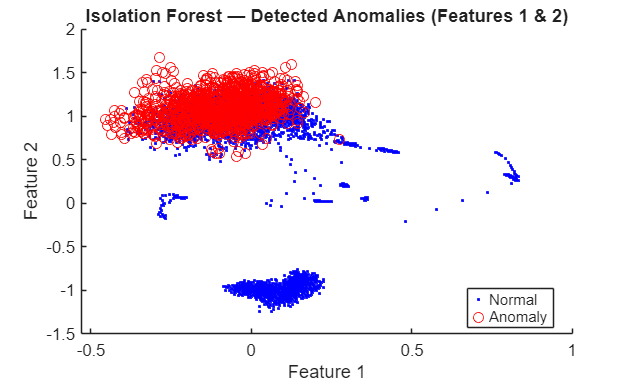


% Visualise Isolation Forest results on first two features
figure
gscatter(feat(:,1), feat(:,2), tf_forest, "br", ".o")
title('Isolation Forest — Detected Anomalies (Features 1 & 2)')
xlabel('Feature 1'); ylabel('Feature 2')
legend('Normal','Anomaly')

### 5.2 Anomaly Detection with Isolation Forest — Score Contour Map

**Source:** [https://www.mathworks.com/help/stats/anomaly-detection-with-isolation-forest.html](https://www.mathworks.com/help/stats/anomaly-detection-with-isolation-forest.html)

**Why it's relevant:** This example visualises the anomaly score landscape as a contour plot, giving process engineers an intuitive map of "danger zones" in feature space. This supports threshold-setting for production monitoring systems.

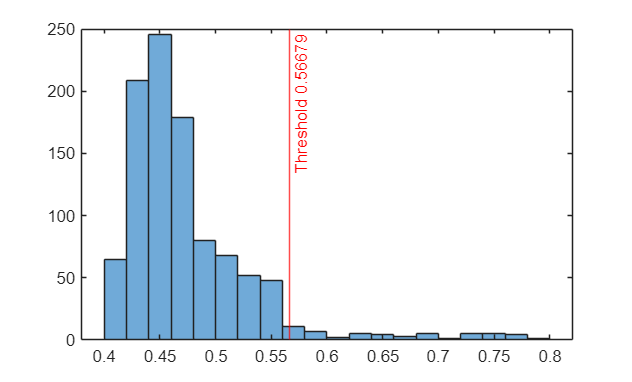

% Generate Sample Data
% Use a Gaussian copula to generate random data points from a bivariate distribution.
rng("default")
rho = [1,0.05;0.05,1];
n = 1000;
u = copularnd("Gaussian",rho,n);

% Add noise to 5% of randomly selected observations to make the observations outliers.
noise = randperm(n,0.05*n);
true_tf = false(n,1);
true_tf(noise) = true;
u(true_tf,1) = u(true_tf,1)*5;

% Train Isolation Forest and Detect Outliers
% Train an isolation forest model by using the iforest function. Specify the fraction of anomalies in the training observations as 0.05.
[f,tf,scores] = iforest(u,ContaminationFraction=0.05);

% f is an IsolationForest object. iforest also returns the anomaly indicators (tf) and anomaly scores (scores) for the training data.
% Plot a histogram of the score values. Create a vertical line at the score threshold corresponding to the specified fraction.
histogram(scores)
xline(f.ScoreThreshold,"r-",join(["Threshold" f.ScoreThreshold]))

% Plot Contours of Anomaly Scores
% Use the trained isolation forest model and the isanomaly function to compute anomaly scores for 2-D grid coordinates around the training observations.
l1 = linspace(min(u(:,1),[],1),max(u(:,1),[],1));
l2 = linspace(min(u(:,2),[],1),max(u(:,2),[],1));
[X1,X2] = meshgrid(l1,l2);
[~,scores_grid] = isanomaly(f,[X1(:),X2(:)]);
scores_grid = reshape(scores_grid,size(X1,1),size(X2,2));
hold off

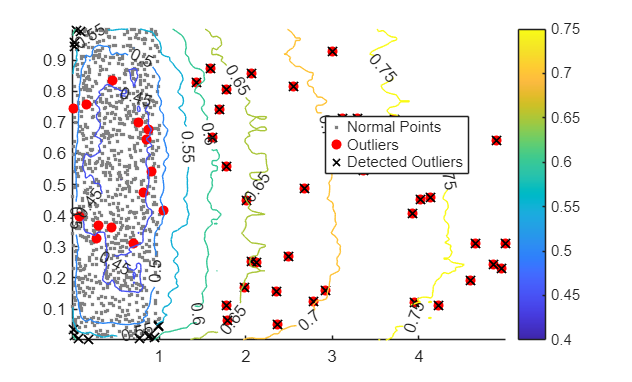


% Create a scatter plot of the training observations and a contour plot of the anomaly scores. Flag true outliers and the outliers detected by iforest.
idx = setdiff(1:1000,noise);
scatter(u(idx,1),u(idx,2),[],[0.5 0.5 0.5],".")
hold on
scatter(u(noise,1),u(noise,2),"ro","filled")
scatter(u(tf,1),u(tf,2),60,"kx",LineWidth=1)
contour(X1,X2,scores_grid,"ShowText","on")
legend(["Normal Points" "Outliers" "Detected Outliers"],Location="best")
colorbar
hold off

## SECTION 6: Clustering — Finding Natural Groupings in Process Data

### 6.1 Evaluate Optimal Number of Clusters

**Source:** [https://www.mathworks.com/help/stats/cluster-evaluation-using-evalclusters.html](https://www.mathworks.com/help/stats/cluster-evaluation-using-evalclusters.html)

**Why it's relevant:** Clustering can automatically group production batches, component reels, or shift periods by process behaviour similarity — without prior labels. The key challenge is selecting k (the number of clusters). evalclusters automatically tests multiple values and scores each with Calinski- Harabasz, silhouette, or gap statistics.

% Load the Fisher iris dataset as a proxy for multi-parameter process data
load fisheriris  % meas (150x4), species (150x1)
X_cl = meas;
y = categorical(species);

% Evaluate k = 1..10 using Calinski-Harabasz criterion
rng("default")
evaluation = evalclusters(X_cl, "kmeans", "CalinskiHarabasz", KList=1:10)

evaluation =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 150
         InspectedK: [1 2 3 4 5 6 7 8 9 10]
    CriterionValues: [NaN 513.9245 561.6278 530.4871 456.1279 469.5068 449.6410 435.8182 413.3837 386.5571]
           OptimalK: 3


  Properties, Methods


fprintf('Optimal number of clusters (Calinski-Harabasz): %d\n', ...
    evaluation.OptimalK)

Optimal number of clusters (Calinski-Harabasz): 3


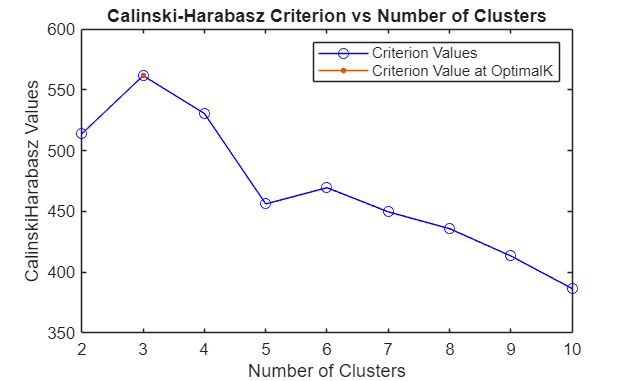


% Visualise criterion values vs number of clusters
figure
plot(evaluation)
legend(["Criterion Values","Criterion Value at OptimalK"])
title('Calinski-Harabasz Criterion vs Number of Clusters')


% Note that identifying three clusters in the data is consistent with having three species in the data.
categories(y)

ans = 3×1 cell array
    {'setosa'    }
    {'versicolor'}
    {'virginica' }


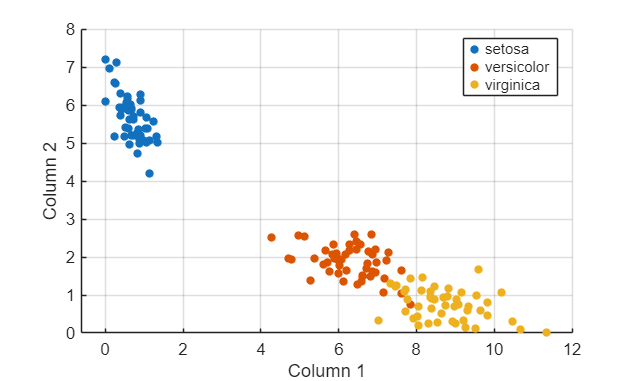


% To visualize the data, compute a nonnegative rank-2 approximation of the data.
reducedX = nnmf(X_cl,2);

% Visualize the three clusters using a scatter plot. Use color to indicate the iris species.
gscatter(reducedX(:,1),reducedX(:,2),y)
xlabel("Column 1")
ylabel("Column 2")
grid on

### 6.2 k-Means Clustering

**Source:** [https://www.mathworks.com/help/stats/k-means-clustering.html](https://www.mathworks.com/help/stats/k-means-clustering.html)

**Why it's relevant:** Once the optimal k is determined, k-means partitions observations into clusters. This can group boards by solder paste profile similarity to identify systematic process shifts across time or operators.

% Cluster into the optimal number of groups from Section 6.1
k_opt = evaluation.OptimalK;
rng("default")
[idx, centroids, sumD] = kmeans(X_cl, k_opt, ...
    Distance="sqeuclidean", Replicates=5, Display="final");

Replicate 1, 4 iterations, total sum of distances = 78.8514.
Replicate 2, 6 iterations, total sum of distances = 78.8557.
Replicate 3, 6 iterations, total sum of distances = 78.8514.
Replicate 4, 3 iterations, total sum of distances = 78.8514.
Replicate 5, 2 iterations, total sum of distances = 78.8514.
Best total sum of distances = 78.8514


fprintf('Total within-cluster sum of distances: %.4f\n', sum(sumD))

Total within-cluster sum of distances: 78.8514


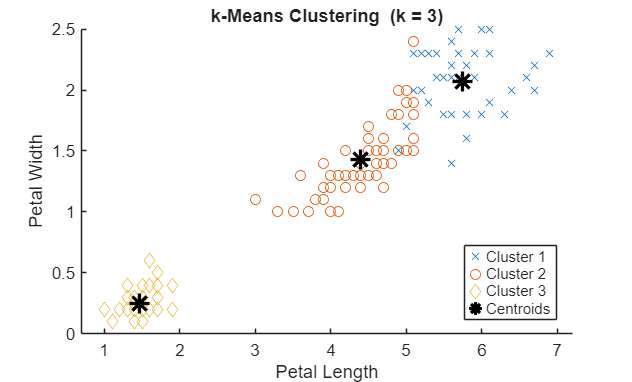


% Scatter plot coloured by cluster assignment
PetalLen = meas(:,3);
PetalWid = meas(:,4);
figure
gscatter(PetalLen, PetalWid, idx, [], "xod")
hold on
plot(centroids(:,3), centroids(:,4), 'k*', 'MarkerSize', 12, 'LineWidth', 2)
title(sprintf('k-Means Clustering  (k = %d)', k_opt))
xlabel('Petal Length'); ylabel('Petal Width')
legend([arrayfun(@(c) sprintf('Cluster %d',c), 1:k_opt, UniformOutput=false), ...
    {'Centroids'}], Location="best")

### 6.3 Cluster Data Using the Live Editor Task (Interactive)

**Source:** [https://www.mathworks.com/help/stats/clusterdatatask.html](https://www.mathworks.com/help/stats/clusterdatatask.html)

**Why it's relevant:** The Cluster Data Live Editor Task lets non-expert users interactively perform k-means or hierarchical clustering with auto-generated MATLAB code — very low barrier to entry for Shuqing's team.

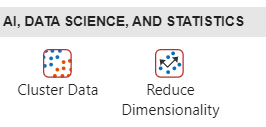

HOW TO USE: 

1. In MATLAB Live Editor, open a new live script (.mlx) 

2. In a code block, type: clustering then press Tab 

3. Select "Cluster Data" from the command completions 

4. In the task panel: Algorithm: k-Means Clustering Input Data: select your variable (e.g., meas) Number of Clusters: Optimal (runs evalclusters automatically) 

5. Click Run — scatter plots and MATLAB code are auto-generated

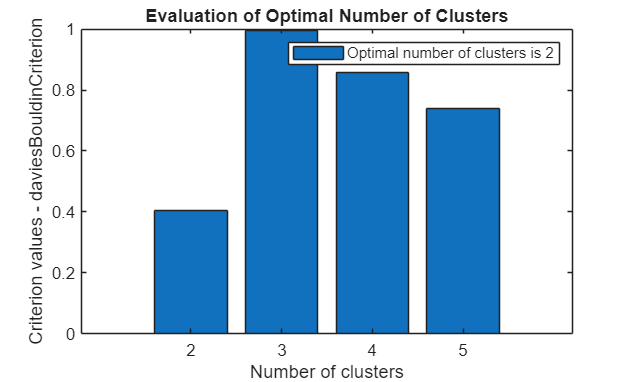

% Select optimal number of clusters (K value) using specified range
fh = @(X3,K)(kmeans(X3,K));
eva = evalclusters(meas,fh,"DaviesBouldin","KList",2:5);
clear fh
K = eva.OptimalK;
clusterIndices = eva.OptimalY;

% Display cluster evaluation criterion values
figure
bar(eva.InspectedK,eva.CriterionValues);
xticks(eva.InspectedK);
xlabel("Number of clusters");
ylabel("Criterion values - daviesBouldinCriterion");
legend("Optimal number of clusters is " + num2str(K))
title("Evaluation of Optimal Number of Clusters")

disp("Optimal number of clusters is " + num2str(K));

Optimal number of clusters is 2


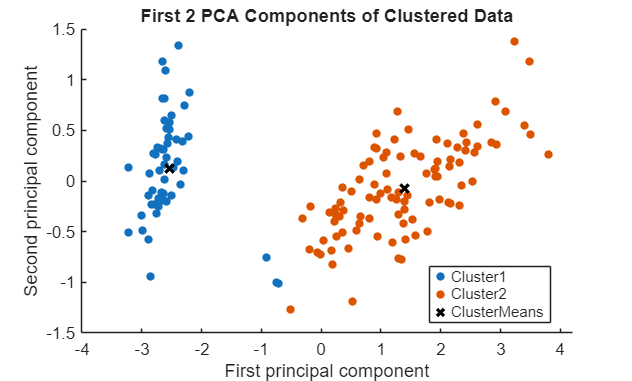

clear K eva

% Calculate centroids
centroids2 = grpstats(meas,clusterIndices,"mean");

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score2] = pca(meas);
clusterMeans = grpstats(score2,clusterIndices,"mean");
h = gscatter(score2(:,1),score2(:,2),clusterIndices);
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i score2
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

## SECTION 7: Dimensionality Reduction & Feature Extraction

### 7.1 PCA — Fit a Plane and Line Using Principal Components Analysis

**Source:** [https://www.mathworks.com/help/stats/fitting-an-orthogonal-regression-using-principal-components-analysis.html](https://www.mathworks.com/help/stats/fitting-an-orthogonal-regression-using-principal-components-analysis.html) 

**Open live script:** openExample('stats/PcaOrthRegrExample')

**Why it's relevant:** PCA reduces high-dimensional sensor data into a smaller set of principal components that capture the most variance — enabling 2D/3D visualisation of process state and feeding faster, more interpretable ML models.

% Generate trivariate normal data (two strongly correlated variables)
rng(5,'twister')
X_pca = mvnrnd([0 0 0], [1 .2 .7; .2 1 0; .7 0 1], 50);

% Fit PCA
[coeff, score, roots] = pca(X_pca);
meanX = mean(X_pca);
n_pts = size(X_pca, 1);

% The first two PCs define the best-fit plane
basis = coeff(:, 1:2)   % plane normal directions

basis =     0.6774   -0.0790
    0.2193    0.9707
    0.7022   -0.2269


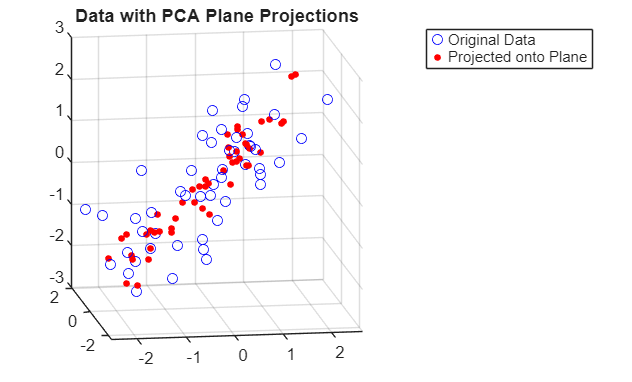


% Plot: raw data in 3D
figure
plot3(X_pca(:,1), X_pca(:,2), X_pca(:,3), 'bo')
grid on
axis square; view(-9, 12)
title('Raw 3D Data')

% Projected onto the fitted plane (first 2 PCs)
Xfit2 = repmat(meanX, n_pts, 1) + score(:,1:2) * coeff(:,1:2)';
hold on
plot3(Xfit2(:,1), Xfit2(:,2), Xfit2(:,3), 'r.', 'MarkerSize', 12)
title('Data with PCA Plane Projections')
legend('Original Data','Projected onto Plane')

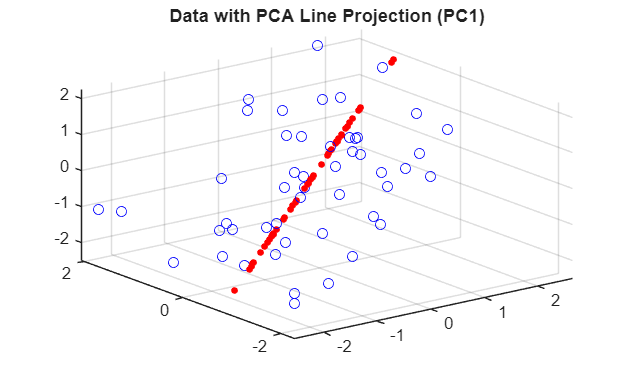


% Projected onto the first PC (line fit)
Xfit1 = repmat(meanX, n_pts, 1) + score(:,1) * coeff(:,1)';
figure
plot3(X_pca(:,1), X_pca(:,2), X_pca(:,3), 'bo'); hold on; grid on
plot3(Xfit1(:,1), Xfit1(:,2), Xfit1(:,3), 'r.', 'MarkerSize', 12)
title('Data with PCA Line Projection (PC1)')

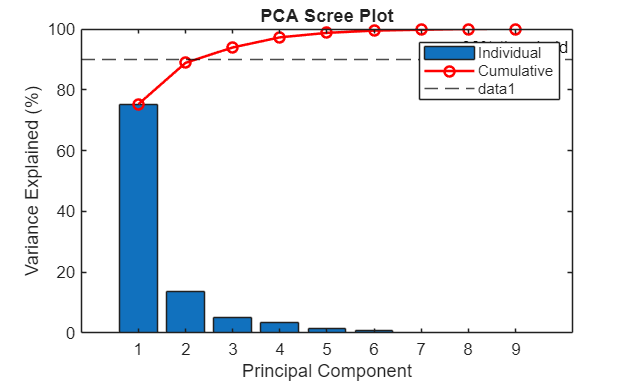


% Explained variance per component
figure
load cities  % 329 US cities, 9 social indicators
[coeff_c, score_c, lat, ~, explained] = pca(ratings);
bar(explained)
hold on
plot(cumsum(explained), 'r-o', 'LineWidth', 1.5)
xlabel('Principal Component')
ylabel('Variance Explained (%)')
title('PCA Scree Plot')
legend('Individual','Cumulative')
yline(90, 'k--', '90% threshold')

### 7.2 Reduce Dimensionality Using Live Editor Task (Interactive)

**Source:** [https://www.mathworks.com/help/stats/reducedimensionalitytask.html](https://www.mathworks.com/help/stats/reducedimensionalitytask.html)

**Why it's relevant:** This interactive task makes PCA accessible to engineers without command- line experience — auto-generating scree plots, biplots, and MATLAB code.

HOW TO USE: 

1. In MATLAB Live Editor, type: pca then press Tab 

2. Select "Reduce Dimensionality" from command completions 

3. In the task panel: 

    Input Data: select your variable (e.g., ratings or sensor matrix) 

    Criterion: Explained Variance (%) -> set to 95% 

    Outputs: check Scree Plot, 2D Scatter Plot, 2D Biplot 

4. The task auto-generates MATLAB code for full reproducibility

% Principal Component Analysis
[coeffs, transformedData, ~, ~, explained2] = pca(ratings);

% Compute number of components from explained variance
enoughExplained = cumsum(explained2)/sum(explained2) >= 95/100;
numberOfComponentsToKeep = find(enoughExplained, 1);
disp("The number of components needed to explain at least 95% of the variance is "+ num2str(numberOfComponentsToKeep))

The number of components needed to explain at least 95% of the variance is 4


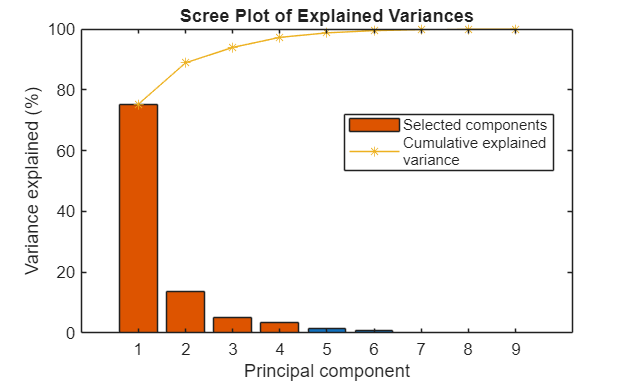


% Display results
figure
colorMap = colormap("lines");
barPlot = bar(explained2);
hold on;
plot(cumsum(explained2),"*-","Color",colorMap(3,:));
hold off;
barPlot(1).FaceColor = "flat";
barPlot(1).CData(1:numberOfComponentsToKeep,:) = repmat( ...
    colorMap(2,:),[numberOfComponentsToKeep 1]);
label = ["Selected components"; sprintf("Cumulative explained\nvariance")];
legend(label,"Location","best");
title("Scree Plot of Explained Variances")
xlabel("Principal component")
ylabel("Variance explained (%)")

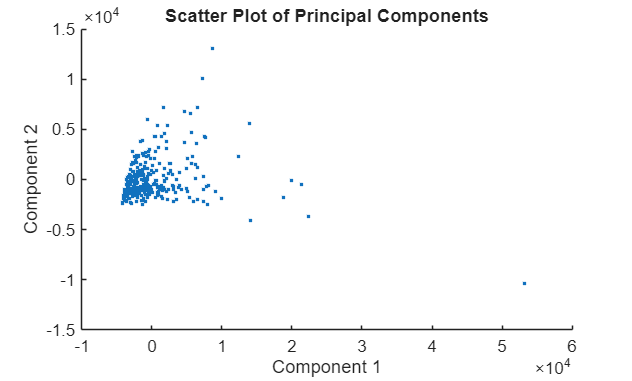

clear barPlot colorMap label explained2

figure
scatter(transformedData(:,1),transformedData(:,2), "Marker", ".");
title("Scatter Plot of Principal Components")
xlabel("Component 1")
ylabel("Component 2")

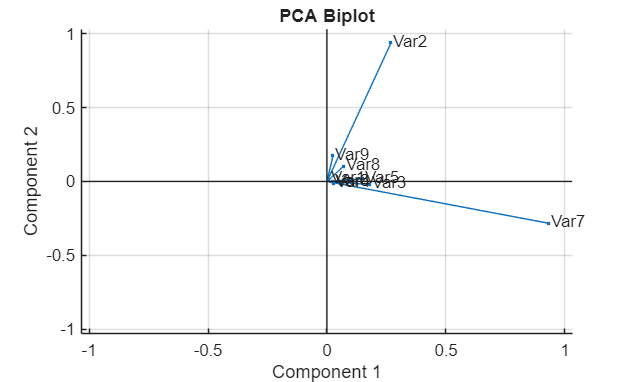


figure
for i2 = 1:size(coeffs, 2)
    varLabels{i2} = ['Var', num2str(i2)];
end
biplot(coeffs(:,[1 2]),"VarLabels",varLabels)
title("PCA Biplot")
xlabel("Component 1")
ylabel("Component 2")

clear coeffs enoughExplained explained2 i2 varLabels
transformedData = transformedData(:,1:numberOfComponentsToKeep);
clear numberOfComponentsToKeep

## SECTION 8: AutoML — Automated Machine Learning (Takes some time to run)

### 8.1 Automated Classifier Selection with fitcauto

**Source:** [https://www.mathworks.com/help/stats/fitcauto.html](https://www.mathworks.com/help/stats/fitcauto.html)

**Open live script:** openExample('stats/AutomaticallySelectClassifierUsingTableDataExample')

**Why it's relevant:** MATLAB's AutoML (fitcauto) trains and compares dozens of model types simultaneously, automatically searching over hyperparameters. For engineers who may not be ML specialists, this dramatically reduces time-to-first-model and removes the burden of manual model selection.

% Load Data
% Load the carbig data set, which contains measurements of cars made in the 1970s and early 1980s.
load carbig

% Categorize the cars based on whether they were made in the USA.
Origin = categorical(cellstr(Origin));
Origin = mergecats(Origin,["France","Japan","Germany", ...
    "Sweden","Italy","England"],"NotUSA");

% Create a table containing the predictor variables Acceleration, Displacement, and so on, as well as the response variable Origin.
cars = table(Acceleration,Displacement,Horsepower, ...
    Model_Year,MPG,Weight,Origin);

% Partition Data
rng("default") % For reproducibility of the data partition
c = cvpartition(Origin,"Holdout",0.2);
trainingIdx = training(c); % Training set indices
carsTrain = cars(trainingIdx,:);
testIdx = test(c); % Test set indices
carsTest = cars(testIdx,:);

% Run fitcauto
Mdl = fitcauto(carsTrain,"Origin");

Learner types to explore: ensemble, knn, nb, net, svm, tree
Total iterations (MaxObjectiveEvaluations): 180
Total time (MaxTime): Inf

|=============================================================================================================================================|
| Iter | Eval   | Validation | Time for training | Observed min    | Estimated min   | Learner      | Hyperparameter:                 Value   |
|      | result | loss       | & validation (sec)| validation loss | validation loss |              |                                         |
|=============================================================================================================================================|
|    1 | Best   |    0.10769 |            19.611 |         0.10769 |         0.10769 |     ensemble | Method:                      LogitBoost |
|      |        |            |                   |                 |                 |              | NumLearningCycles:                  291 |
|


% Evaluate Test Set Performance
testAccuracy = 1 - loss(Mdl,carsTest,"Origin")

testAccuracy = 0.9269

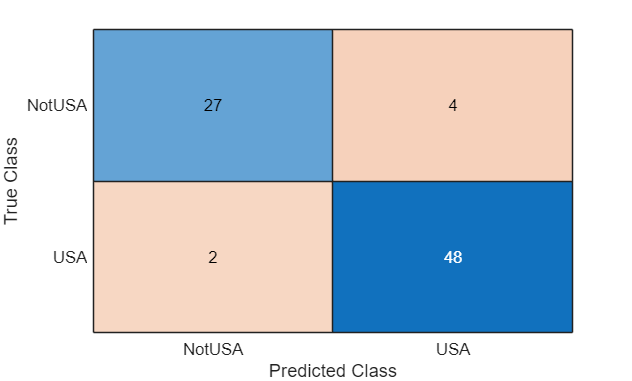

confusionchart(carsTest.Origin,predict(Mdl,carsTest))

## SECTION 9: Predictive Maintenance — Equipment Health Monitoring (Demo needs MATLAB Production Server)

### 9.1 Monitor Equipment State of Health Using Drift-Aware Learning

**Source:** [https://www.mathworks.com/help/stats/monitoring-state-of-health-of-system-using-drift-aware-learning.html](https://www.mathworks.com/help/stats/monitoring-state-of-health-of-system-using-drift-aware-learning.html) 

**Open example:** openExample('stats/MonitorEquipmentStateOfHealthUsingDriftAwareLearningExample')

**Why it's relevant:** This example automates health monitoring of a manufacturing cooling system using an incremental drift-aware Naive Bayes classifier that updates continuously as new sensor data arrives. This maps directly to monitoring placement machine accuracy drift, printer clogging trends, or conveyor wear — alerting before costly failures.

KEY CONCEPTS: incrementalDriftAwareLearner — adaptive model that detects when the data distribution shifts (concept drift) and automatically retrains fit(model, X, Y) — update model with each batch of labeled data predict(model, X) — predict health state of new sensor readings perObservationLoss(...) — compute rolling misclassification loss

The example includes a full App Designer monitoring dashboard. 

Simplified skeleton (illustrates the incremental update loop):

## SECTION 10: Design of Experiments (DOE)

### 10.1 Full and Fractional Factorial Experiment Design

**Source:** [https://www.mathworks.com/help/stats/industrial-statistics.html](https://www.mathworks.com/help/stats/industrial-statistics.html)

**Why it's relevant:** DOE is a structured approach to understanding which process parameters (e.g., reflow oven temperature, conveyor speed, squeegee pressure) most affect a quality outcome. Compared to one-factor-at-a-time testing, DOE explores the design space efficiently and reveals interaction effects.

% --- Full Factorial Design (2^3: 3 factors at 2 levels = 8 runs) ---
dFull     = fullfact([2 2 2]);     % design matrix (coded 1/2)
dFullCode = 2*dFull - 3;           % convert to -1/+1 coding
fprintf('Full factorial (2^3): %d runs\n', size(dFull,1))

Full factorial (2^3): 8 runs


disp(array2table(dFullCode, VariableNames=["Temperature","Pressure","Speed"]))

    Temperature    Pressure    Speed
    ___________    ________    _____

        -1            -1        -1  
         1            -1        -1  
        -1             1        -1  
         1             1        -1  
        -1            -1         1  
         1            -1         1  
        -1             1         1  
         1             1         1  




% --- Fractional Factorial Design (2^(3-1) half-fraction = 4 runs) ---
% Uses generator C=AB to alias higher-order interactions
dFrac = fracfact('a b ab');
fprintf('\nFractional factorial (2^(3-1)): %d runs\n', size(dFrac,1))


Fractional factorial (2^(3-1)): 4 runs


disp(array2table(dFrac, VariableNames=["Temperature","Pressure","Speed"]))

    Temperature    Pressure    Speed
    ___________    ________    _____

        -1            -1         1  
        -1             1        -1  
         1            -1        -1  
         1             1         1  



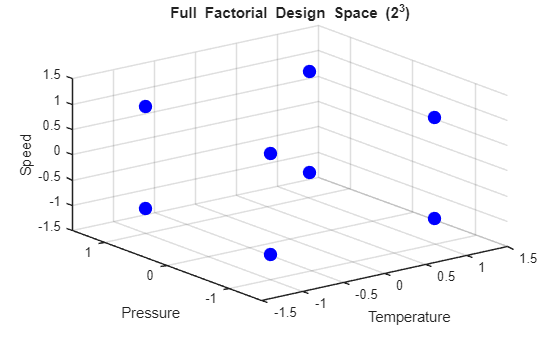


% Visualise the full factorial design space as a cube
figure
scatter3(dFullCode(:,1), dFullCode(:,2), dFullCode(:,3), 100, 'bo', 'filled')
xlabel('Temperature'); ylabel('Pressure'); zlabel('Speed')
title('Full Factorial Design Space (2^3)')
grid on; axis([-1.5 1.5 -1.5 1.5 -1.5 1.5])


% --- Simulate a process response and fit a linear model ---
rng(0)
responseY = 5 + 2*dFullCode(:,1) - 1.5*dFullCode(:,2) + ...
            0.5*dFullCode(:,3) + 0.8*dFullCode(:,1).*dFullCode(:,2) + ...
            randn(8,1)*0.3;

tblDOE = array2table([dFullCode, responseY], ...
    VariableNames=["Temperature","Pressure","Speed","Yield"]);

% Fit model with main effects and all 2-way interactions
mdlDOE = fitlm(tblDOE, 'interactions');
disp(mdlDOE)


Linear regression model:
    Yield ~ 1 + Temperature*Pressure + Temperature*Speed + Pressure*Speed

Estimated Coefficients:
                            Estimate      SE        tStat      pValue  
                            ________    _______    _______    _________

    (Intercept)               4.9961    0.02167     230.55    0.0027613
    Temperature               2.1338    0.02167     98.466    0.0064652
    Pressure                 -1.6076    0.02167    -74.187    0.0085808
    Speed                    0.42295    0.02167     19.518     0.032589
    Temperature:Pressure     0.95853    0.02167     44.233      0.01439
    Temperature:Speed       -0.19753    0.02167    -9.1154     0.069562
    Pressure:Speed           0.17498    0.0


% ANOVA to identify which factors are statistically significant
figure
anova(mdlDOE, 'summary')

ans = 5×5 table
                     SumSq      DF     MeanSq        F        pValue 
                   _________    __    _________    ______    ________

    Total             66.442    7        9.4917                      
    Model             66.438    6        11.073    2947.5    0.014098
    . Linear          58.531    3         19.51    5193.4      0.0102
    . Nonlinear       7.9073    3        2.6358    701.62    0.027744
    Residual       0.0037567    1     0.0037567                      


## SECTION 11: Integration with Other Toolboxes

### 11.1 Wavelet Time Scattering for Vibration Signal Classification

**Source:** [https://www.mathworks.com/help/wavelet/ug/wavelet-time-scattering-signal-classification.html](https://www.mathworks.com/help/wavelet/ug/wavelet-time-scattering-signal-classification.html)

**Why it's relevant:** Wavelet time scattering extracts rich, translation-invariant features from vibration or acoustic signals — for example, classifying machine sounds or vibration waveforms to detect placement head faults or feeder abnormalities. These features pair with the classification methods in Sections 4-5.

Key workflow: 

    1. sn = waveletScattering(SignalLength=N, SamplingFrequency=Fs) 

    2. feats = featureMatrix(sn, signal, 'Transform','log') 

    3. Train an SVM/ensemble on the extracted features 

    4. Deploy with saveLearnerForCoder + MATLAB Coder for edge deployment

>> openExample('wavelet/WaveletScatteringSignalClassificationExample')

### 11.2 Curve Fitting for Process Parametric Modelling

**Source:** [https://www.mathworks.com/help/curvefit/](https://www.mathworks.com/help/curvefit/)

**Why it's relevant:**  It can be combined with the Statistics & ML Toolbox to fit parametric models (polynomial, exponential, custom equations) to process data — e.g., modelling solder paste viscosity vs. temperature, fitting wear/degradation curves, or characterising placement accuracy drift vs. operating hours.

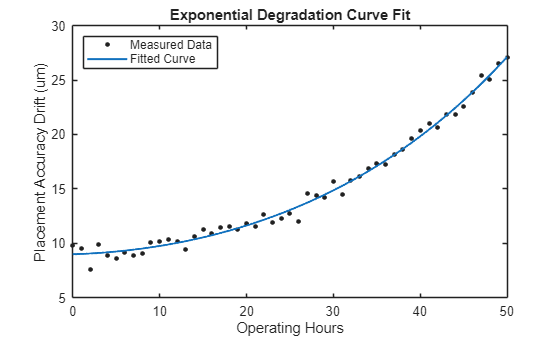

% Example: fit an exponential degradation curve to simulated wear data
t_hours = (0:50)';
accuracy_drift = 5 + 3*exp(0.04*t_hours) + randn(51,1)*0.5;

[fitResult, gof] = fit(t_hours, accuracy_drift, 'exp2');

figure
plot(fitResult, t_hours, accuracy_drift)
xlabel('Operating Hours')
ylabel('Placement Accuracy Drift (um)')
title('Exponential Degradation Curve Fit')
legend('Measured Data','Fitted Curve', Location='NorthWest')

fprintf('Goodness of fit R-squared: %.4f\n', gof.rsquare)

Goodness of fit R-squared: 0.9902
